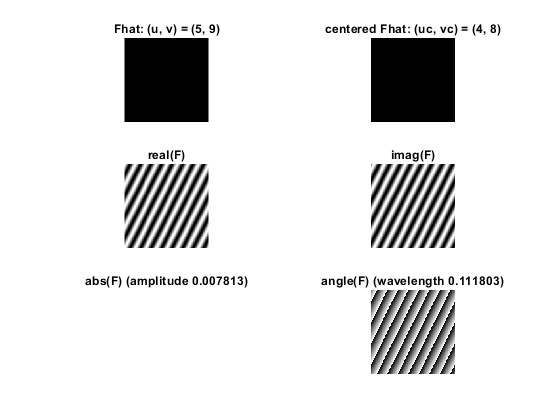

fftwave(5, 9, 128)

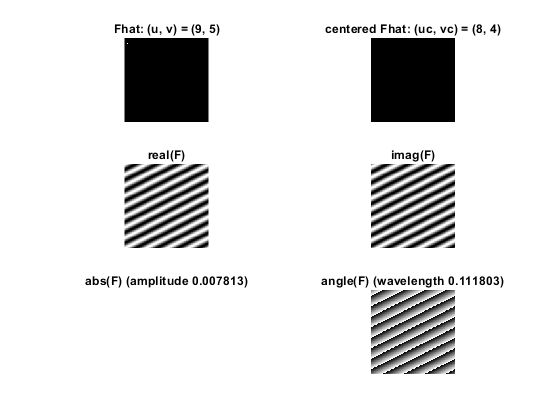

fftwave(9, 5, 128)

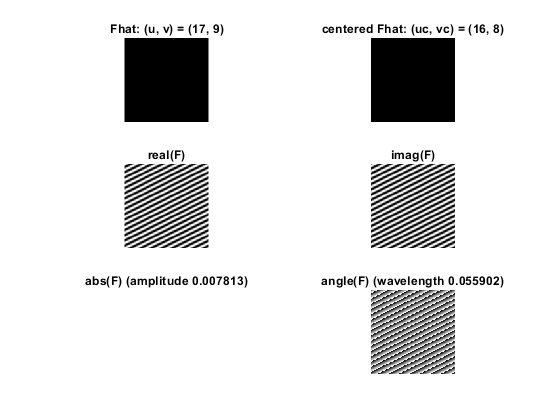

fftwave(17, 9, 128)

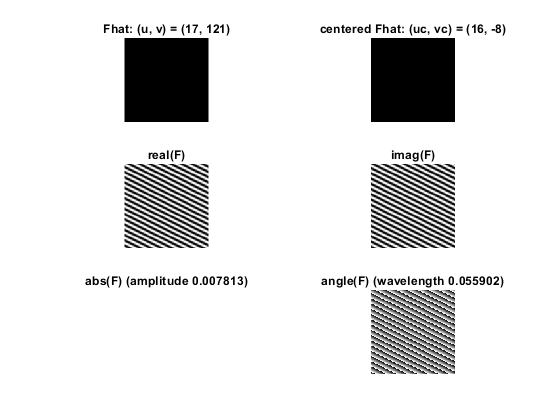

fftwave(17, 121, 128)

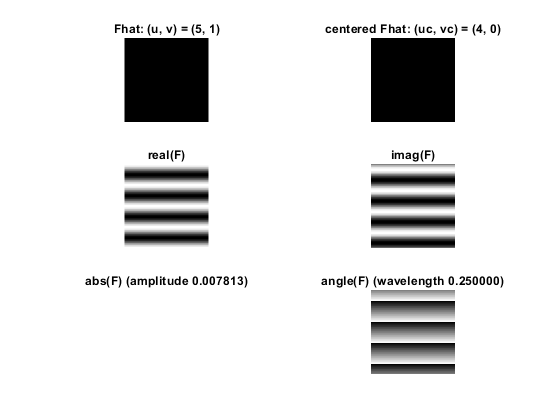

fftwave(5, 1, 128)

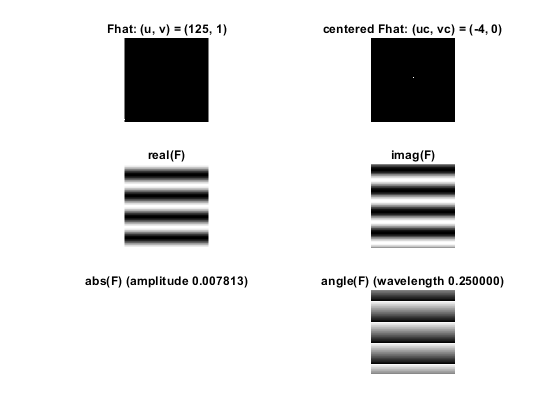

fftwave(125, 1, 128)

% Q 7-9
close all
F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
H = F + 2 * G;

Fhat = fft2(F);
Ghat = fft2(G);
Hhat = fft2(H);

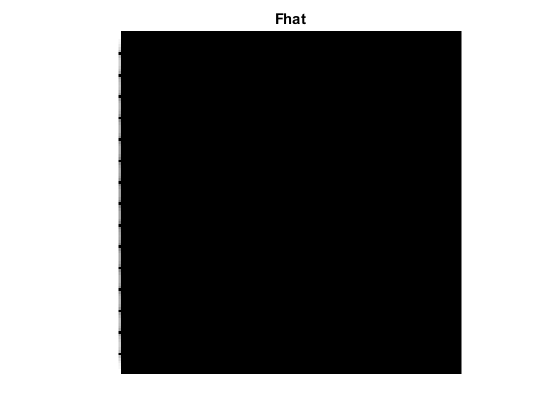

showgrey(log(1 + abs(Fhat)))
title('Fhat')

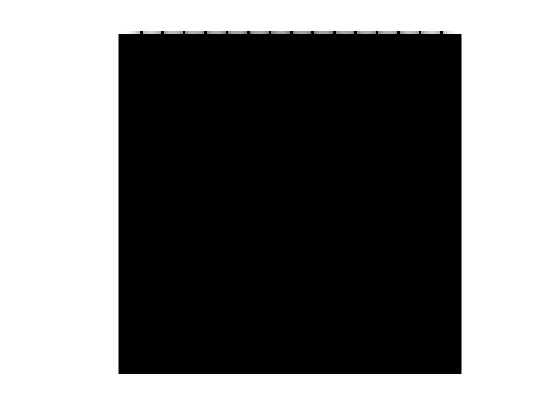

showgrey(log(1 + abs(Ghat)));

title('Ghat')

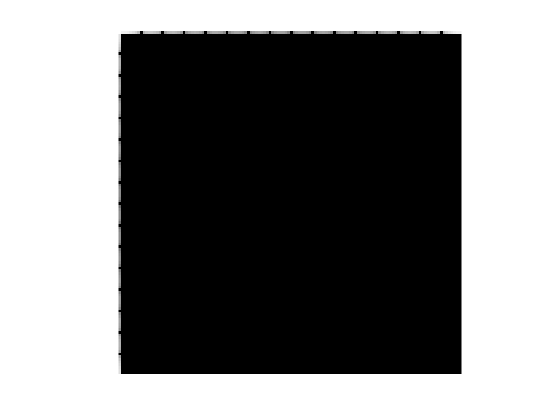

showgrey(log(1 + abs(Hhat)));

title('Hhat')

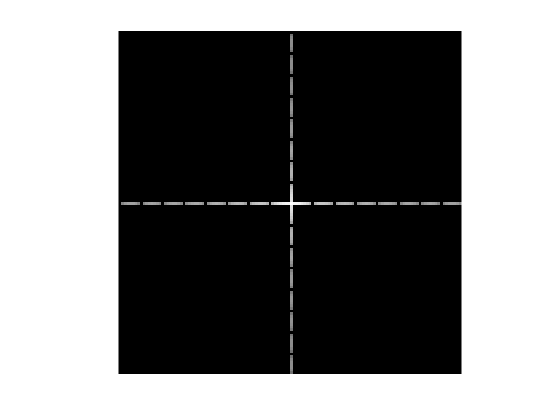


showgrey(log(1 + abs(fftshift(Hhat))));

title('Hhat centered')

% Q 10
disp("Question 10")

Question 10


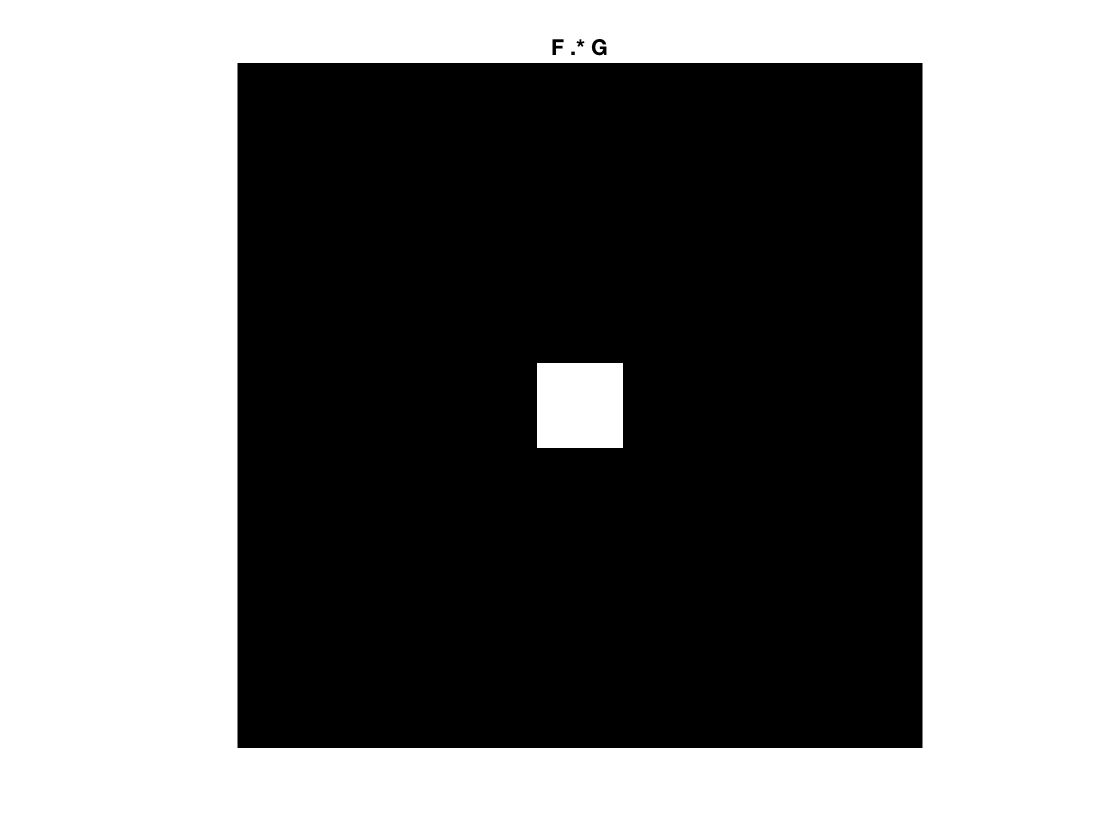

sz = 128;

showgrey(F .* G);
title('F .* G')

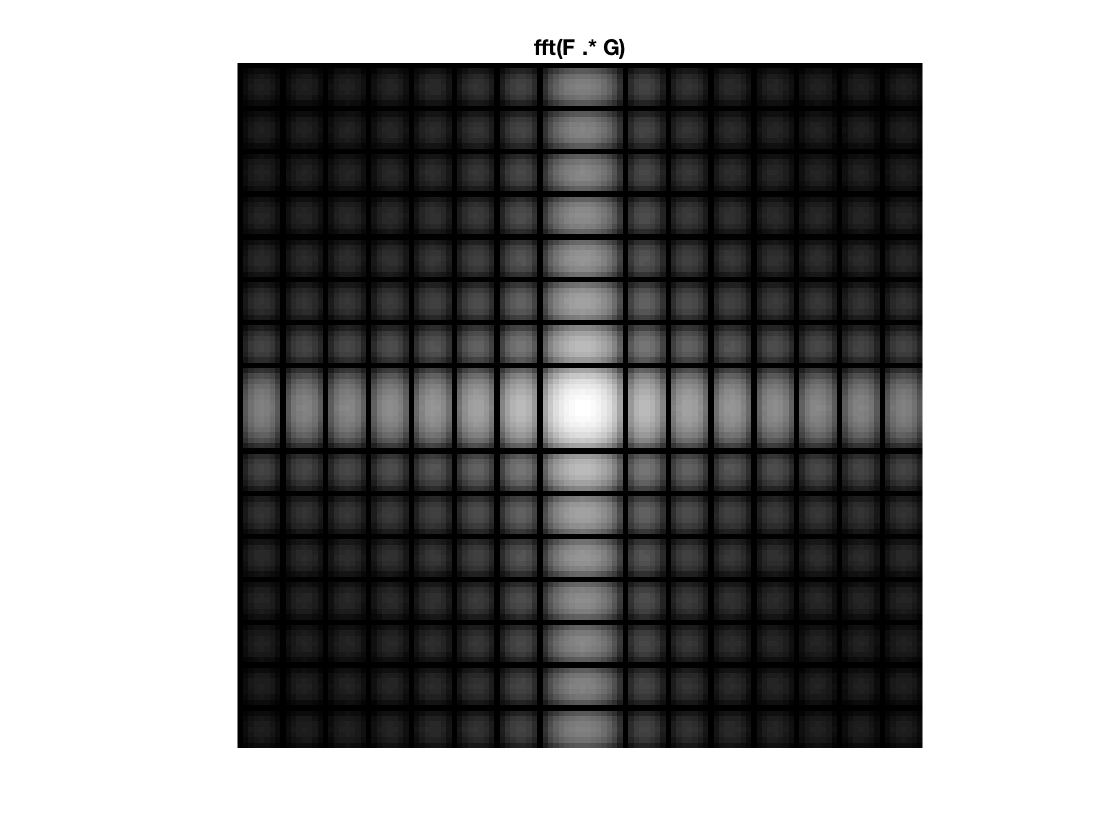


showfs(fft2(F .* G));
title('fft(F .* G)')

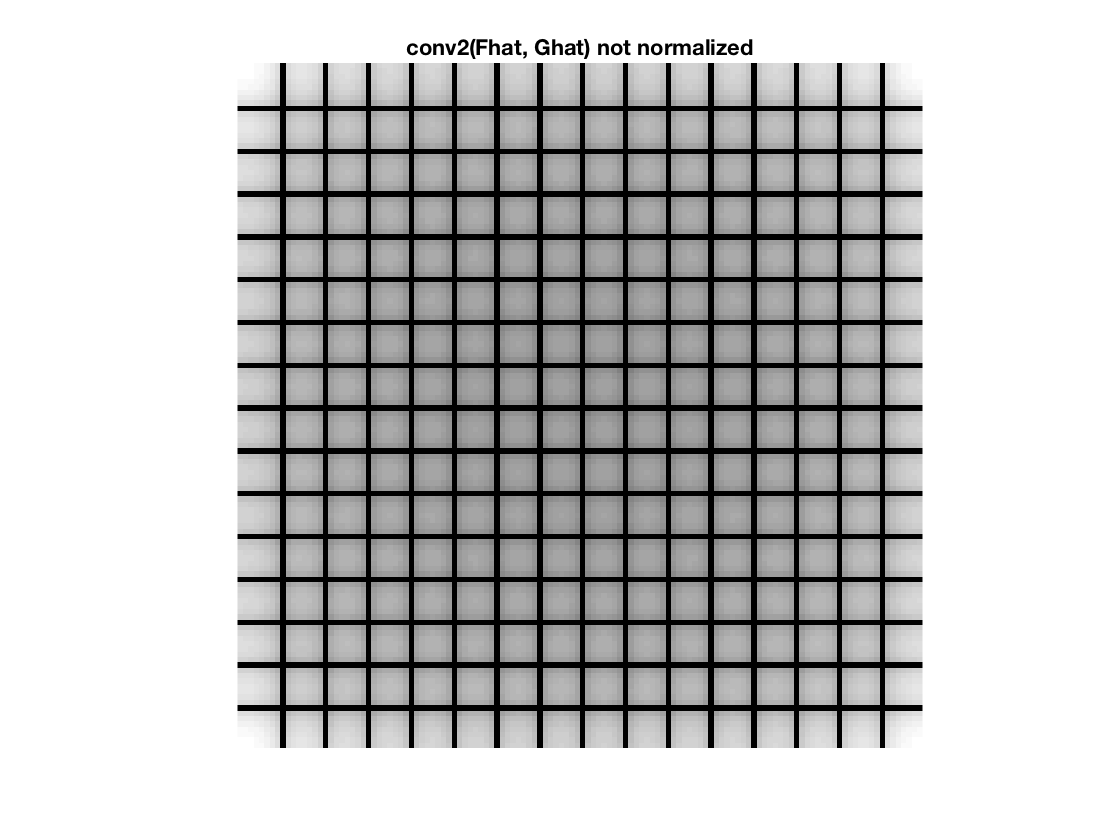

%FGhat = conv2(ftshift(fFhat), fftshift(Ghat));
Fhat_shifted = fftshift(Fhat);
Ghat_shifted = fftshift(Ghat);

% same padding to get central part that's the same size
FGhat = conv2(Fhat_shifted, Ghat_shifted, "same");
showfs(FGhat);
title('conv2(Fhat, Ghat) not normalized')

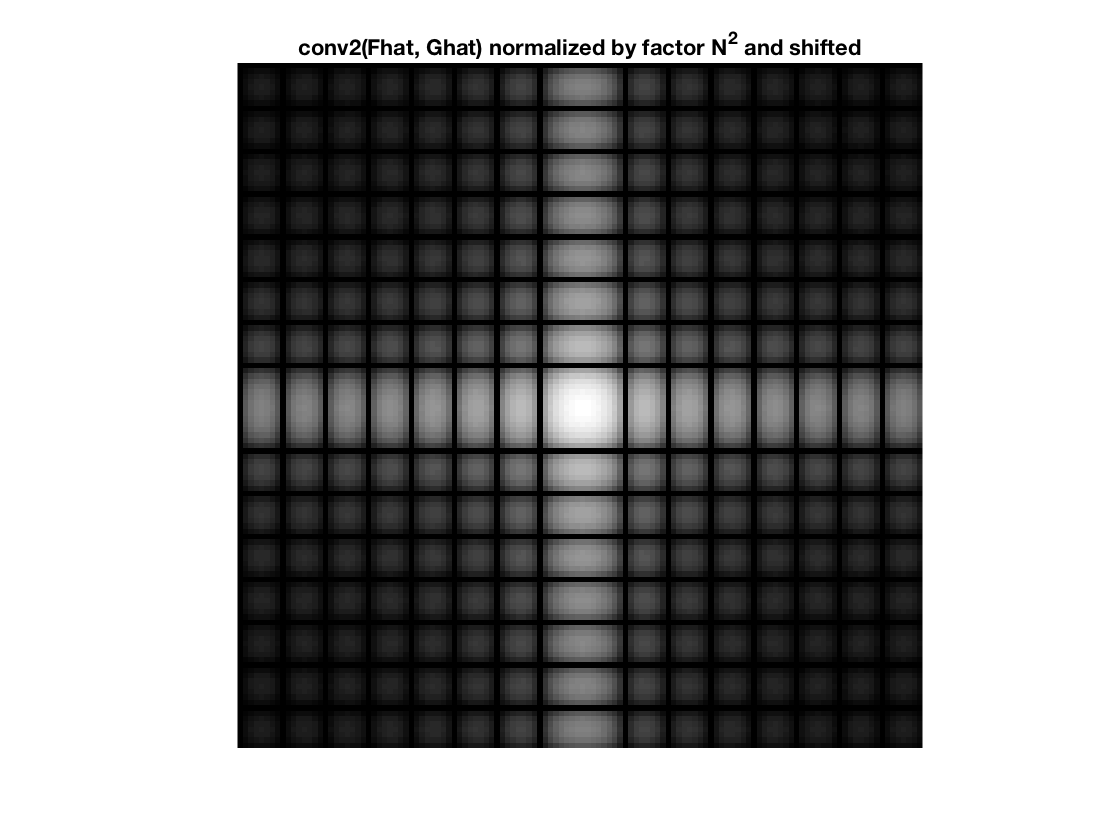

%showfs(fftshift(conv2(Fhat_shifted ./ sz, Ghat_shifted ./ sz,"same")))
showfs(fftshift(FGhat / sz.^2));
title('conv2(Fhat, Ghat) normalized by factor N^2 and shifted')

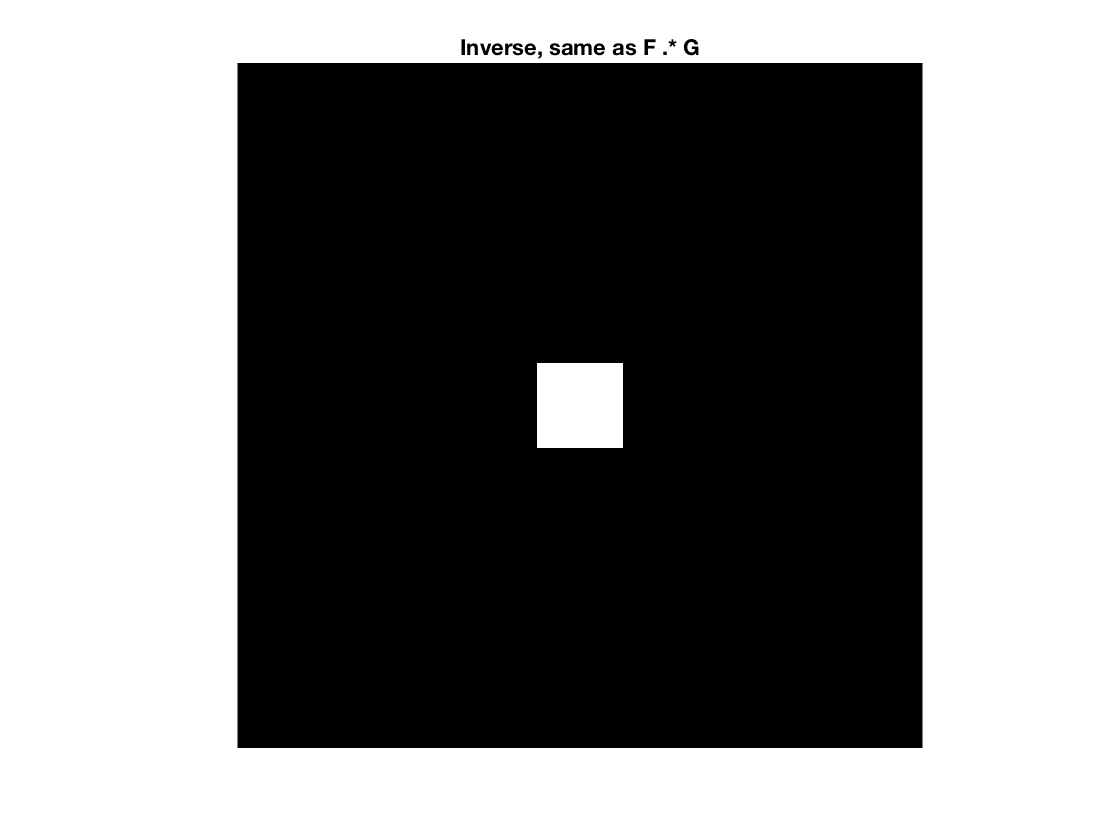

showgrey(abs(ifft2(FGhat)));
title('Inverse, same as F .* G')

% Q 11
disp("Question 11")

Question 11


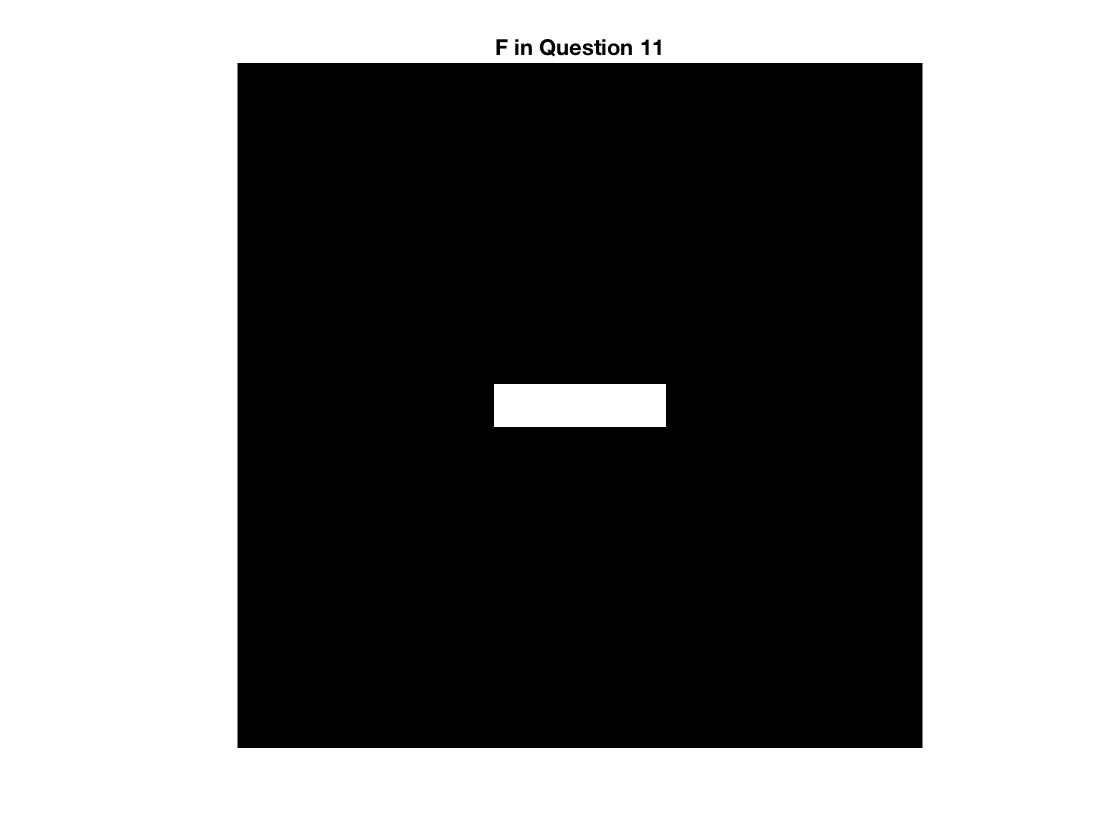

F = [zeros(60, 128); ones(8, 128); zeros(60, 128)] .* ...
[zeros(128, 48) ones(128, 32) zeros(128, 48)];
showgrey(F);
title("F in Question 11")

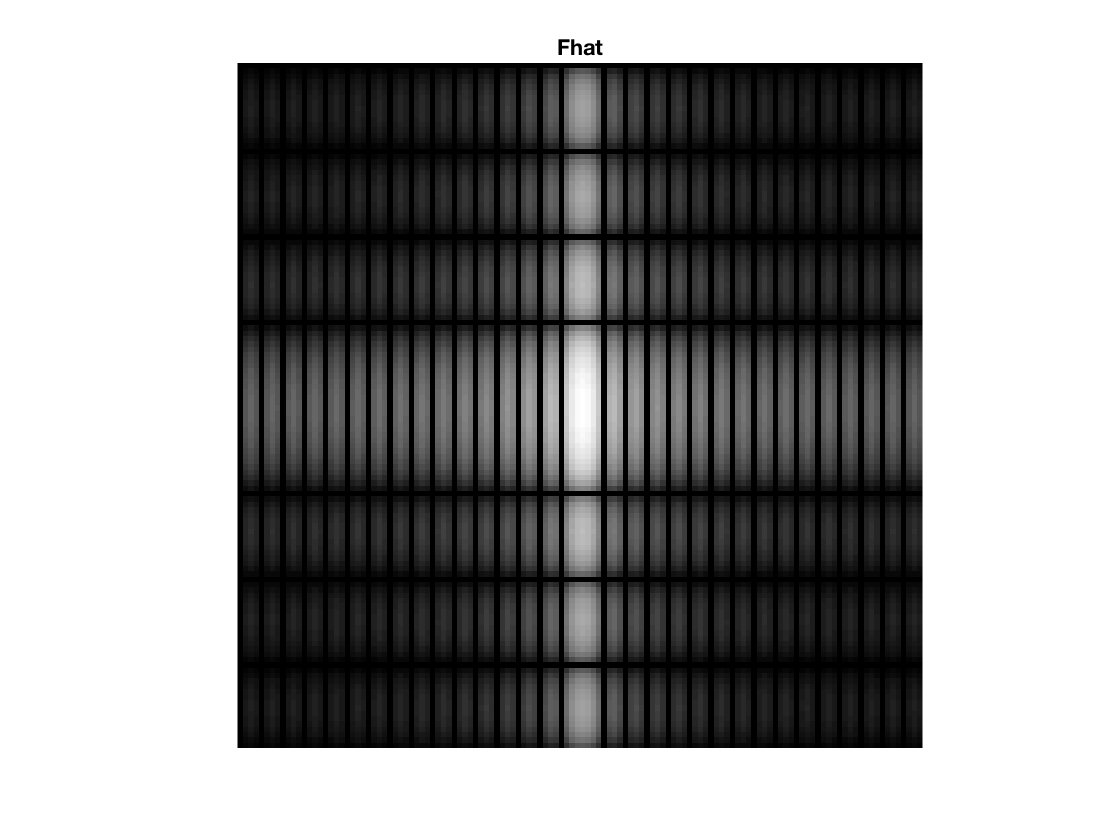


showfs(fft2(F));
title("Fhat")

% Q 12
figure
alpha = 30

alpha = 30

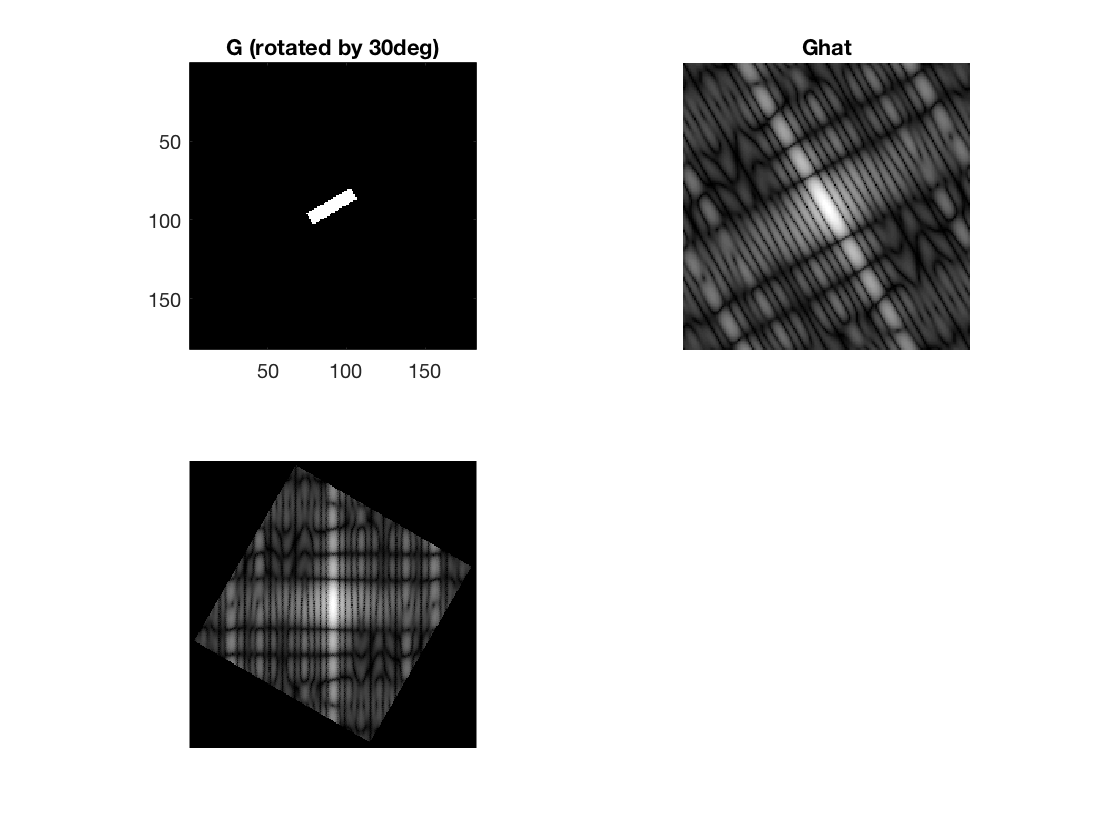

G = rot(F, alpha); % rotated by alpha degrees
subplot(2,2,1);
showgrey(G);
title("G (rotated by 30deg)")
axis on

Ghat = fft2(G);
subplot(2,2,2);
showfs(Ghat);
title("Ghat")

Hhat = rot(fftshift(Ghat), -alpha );
subplot(2,2,3);
showgrey(log(1 + abs(Hhat)));

figure
alpha = 45

alpha = 45

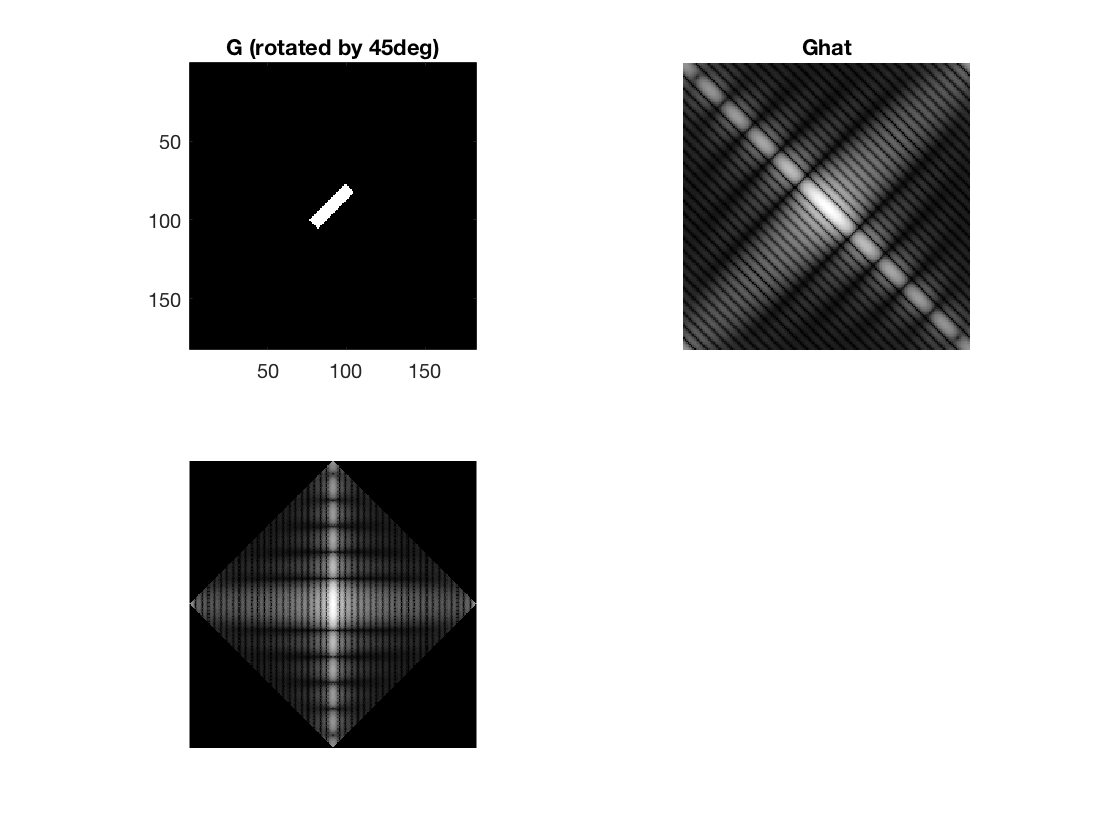

G = rot(F, alpha); % rotated by alpha degrees
subplot(2,2,1);
showgrey(G);
title("G (rotated by 45deg)")
axis on

Ghat = fft2(G);
subplot(2,2,2);
showfs(Ghat);
title("Ghat")

Hhat = rot(fftshift(Ghat), -alpha );
subplot(2,2,3);
showgrey(log(1 + abs(Hhat)));

figure
alpha = 60

alpha = 60

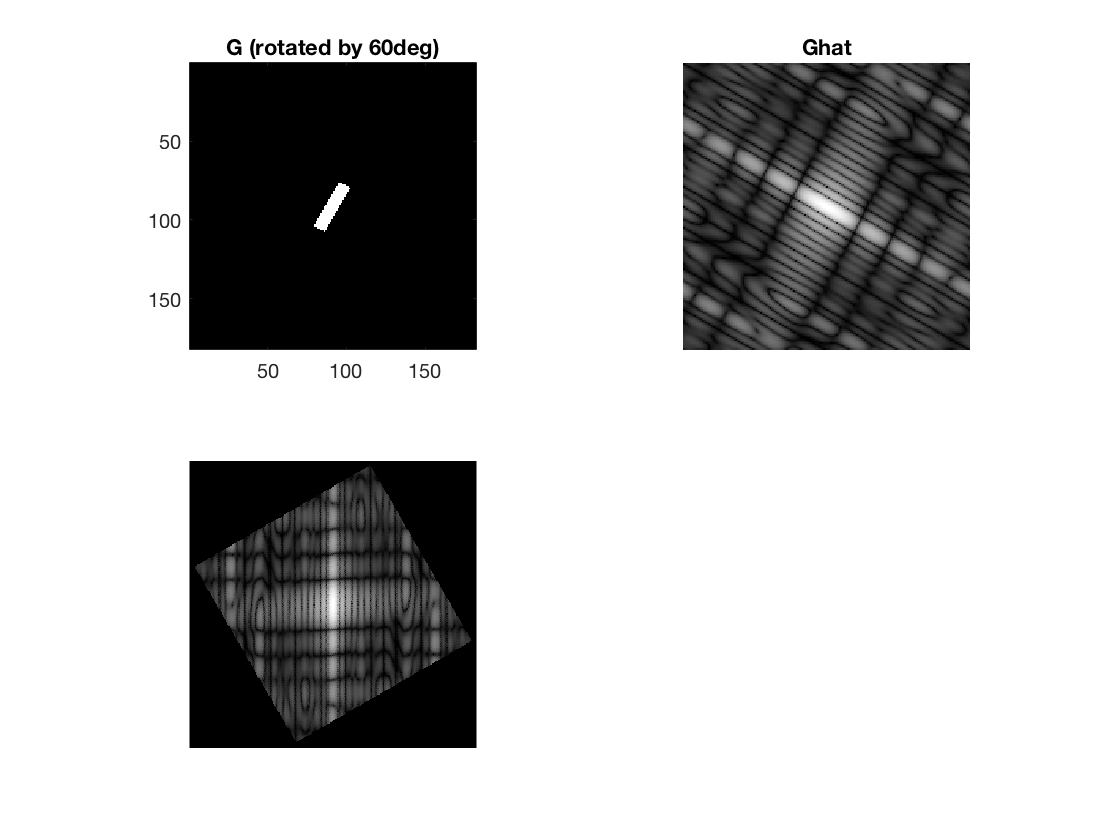

G = rot(F, alpha); % rotated by alpha degrees
subplot(2,2,1);
showgrey(G);
title("G (rotated by 60deg)")
axis on

Ghat = fft2(G);
subplot(2,2,2);
showfs(Ghat);
title("Ghat")

Hhat = rot(fftshift(Ghat), -alpha );
subplot(2,2,3);
showgrey(log(1 + abs(Hhat)));

figure
alpha = 90

alpha = 90

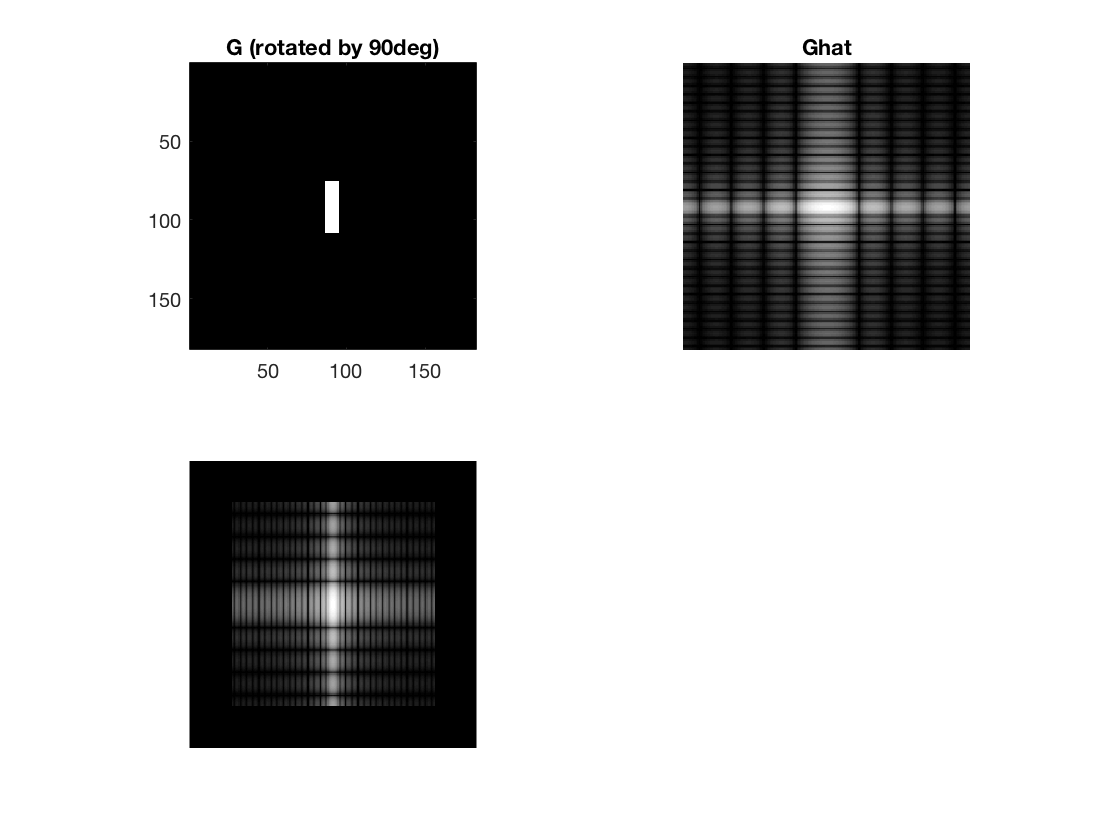

G = rot(F, alpha); % rotated by alpha degrees
subplot(2,2,1);
showgrey(G);
title("G (rotated by 90deg)")
axis on

Ghat = fft2(G);
subplot(2,2,2);
showfs(Ghat);
title("Ghat")

Hhat = rot(fftshift(Ghat), -alpha );
subplot(2,2,3);
showgrey(log(1 + abs(Hhat)));

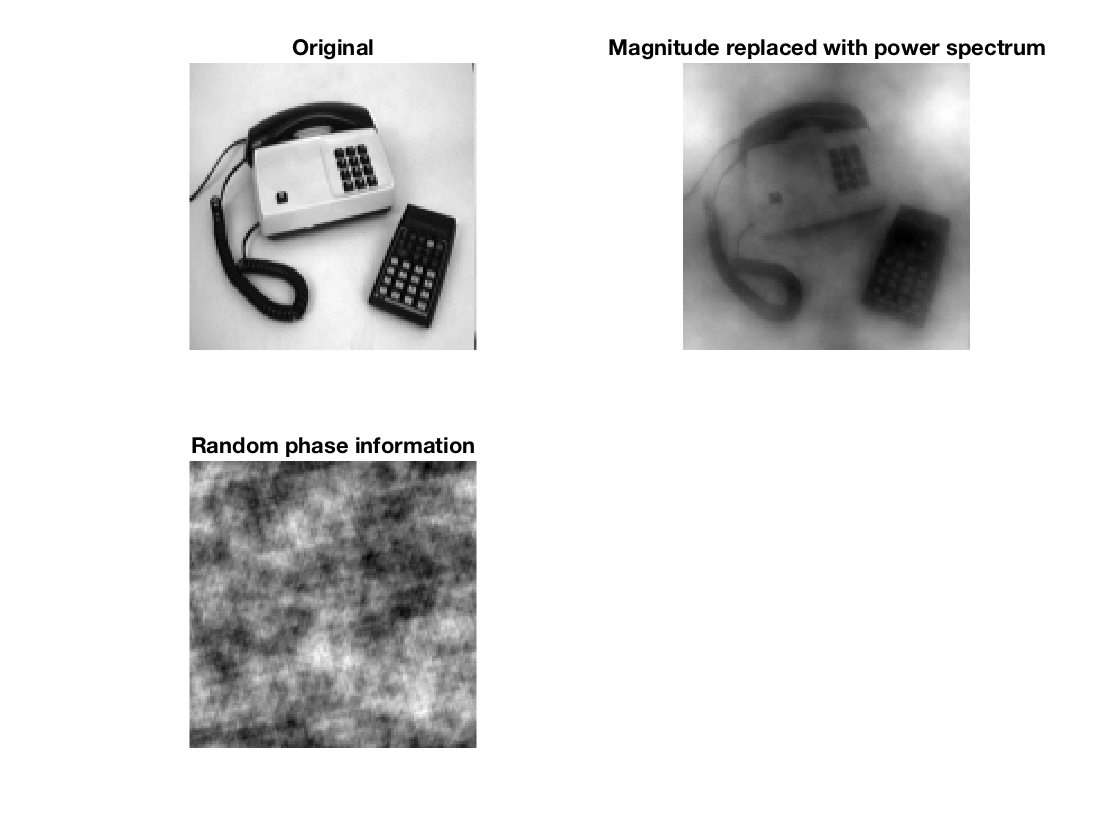

close all
% Q 13
img = phonecalc128;
subplot(2,2,1);
showgrey(img);
title("Original")

subplot(2,2,2);
showgrey(pow2image(img, 1e-9));
title("Magnitude replaced with power spectrum")

subplot(2,2,3);
showgrey(randphaseimage(img));
title("Random phase information")

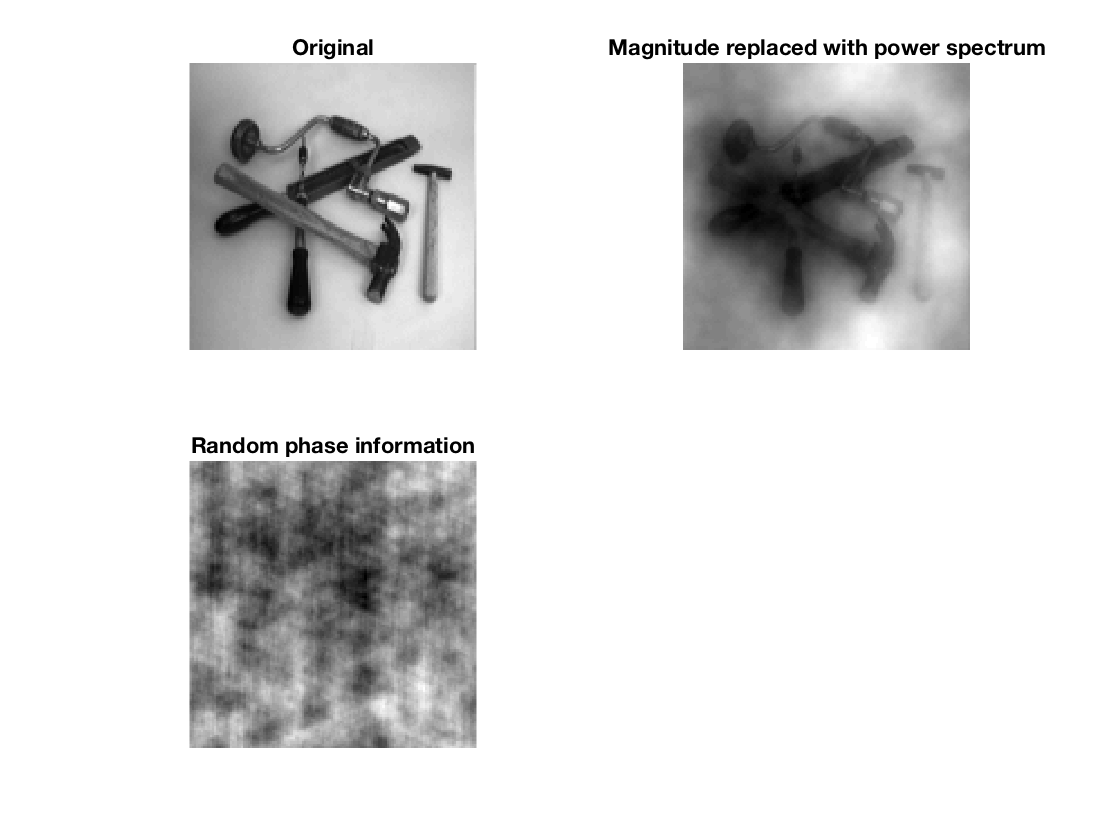

img = few128;
subplot(2,2,1);
showgrey(img);
title("Original")

subplot(2,2,2);
showgrey(pow2image(img, 1e-9));
title("Magnitude replaced with power spectrum")

subplot(2,2,3);
showgrey(randphaseimage(img));
title("Random phase information")

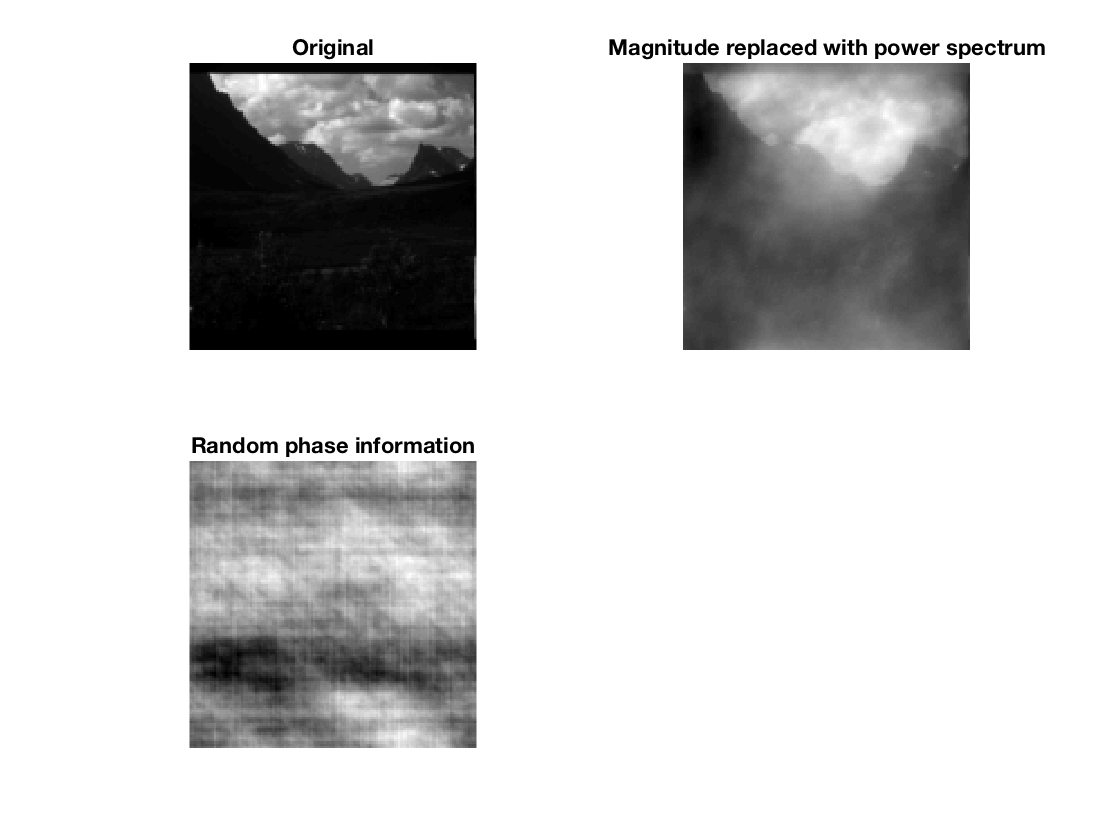

img = nallo128;
subplot(2,2,1);
showgrey(img);
title("Original")

subplot(2,2,2);
showgrey(pow2image(img, 1e-9));
title("Magnitude replaced with power spectrum")

subplot(2,2,3);
showgrey(randphaseimage(img));
title("Random phase information")

% Q 14
close all
% t = 100;
% showgrey(img);
% filtered = gaussfft(img, t);
% showgrey(filtered);

% psf = gaussfft(deltafcn(128, 128), t);
% showgrey(psf);
% var = variance(psf);
% display(var);
% display(t * eye(2));

t = 0.1;
subplot(3,2,1);
psf = gaussfft(deltafcn(128, 128), t);
showgrey(psf);
title("t = 0.1")
var_01 = variance(psf);
display(var_01);

var_01 =     0.0133    0.0000
    0.0000    0.0133



t = 0.3;
subplot(3,2,2);
psf = gaussfft(deltafcn(128, 128), t);
showgrey(psf);
title("t = 0.3")
var_03 = variance(psf);
display(var_03);

var_03 =     0.2811    0.0000
    0.0000    0.2811



t = 1.0;
subplot(3,2,3);
psf = gaussfft(deltafcn(128, 128), t);
showgrey(psf);
title("t = 1.0")
var_1 = variance(psf);
display(var_1);

var_1 =     1.0000    0.0000
    0.0000    1.0000



t = 10.0;
subplot(3,2,4);
psf = gaussfft(deltafcn(128, 128), t);
showgrey(psf);
title("t = 10.0")
var_10 = variance(psf);
display(var_10);

var_10 =    10.0000    0.0000
    0.0000   10.0000


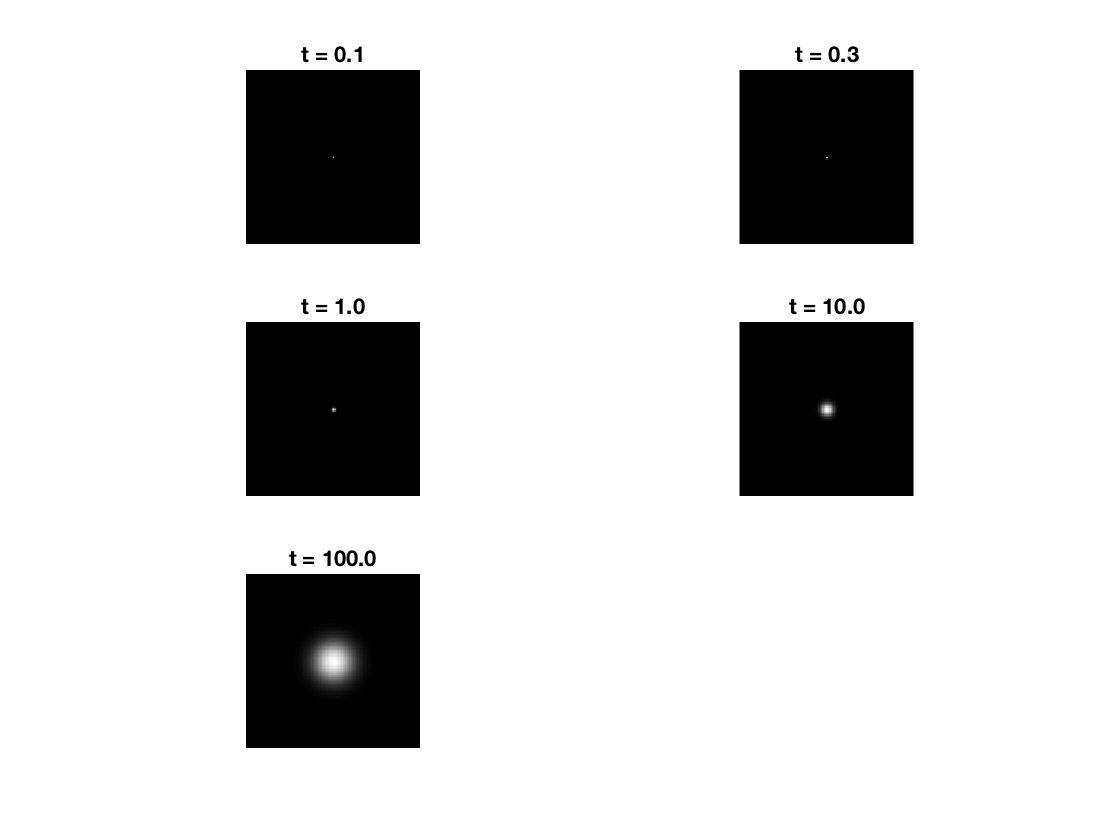


t = 100.0;
subplot(3,2,5);
psf = gaussfft(deltafcn(128, 128), t);
showgrey(psf);
title("t = 100.0")

var_100 = variance(psf);
display(var_100);

var_100 =   100.0000   -0.0000
   -0.0000  100.0000


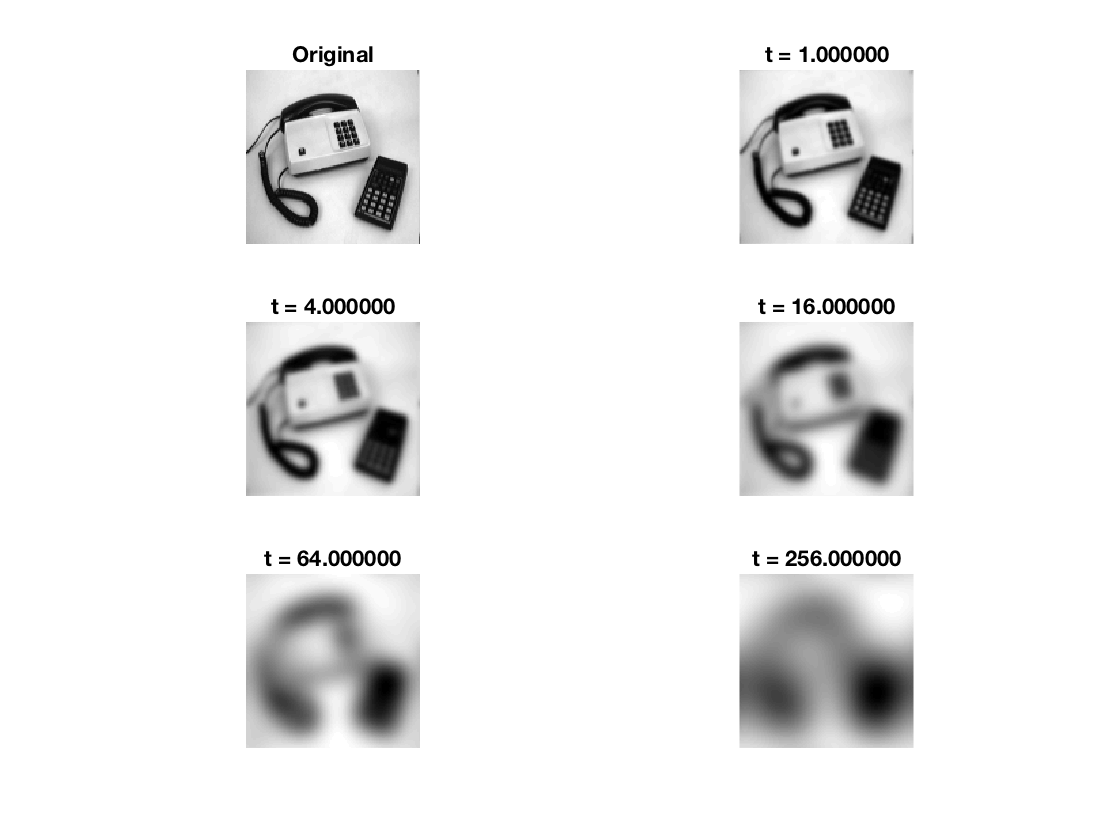

% Q 16
tValues = [1.0, 4.0, 16.0, 64.0, 256.0];
img1 = phonecalc128;

subplot(3,2,1);
showgrey(img1);
title("Original");

for i = 1:length(tValues)
    t = tValues(i);
    subplot(3,2,1+i);
    showgrey(gaussfft(img1, t));
    title(sprintf("t = %f", t));
end

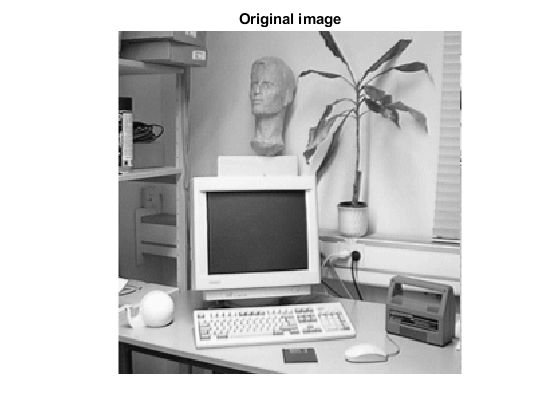

close all
office = office256;
add = gaussnoise(office, 16);
sap = sapnoise(office, 0.1, 255);

showgrey(office);
title("Original image")

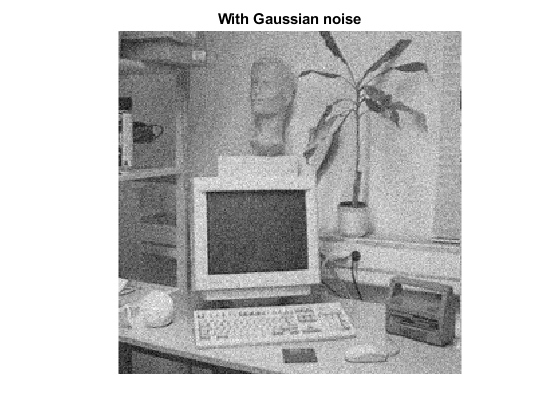

showgrey(add);
title("With Gaussian noise")

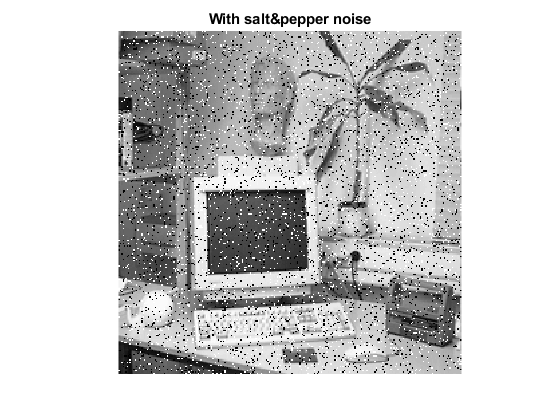


showgrey(sap);
title("With salt&pepper noise")

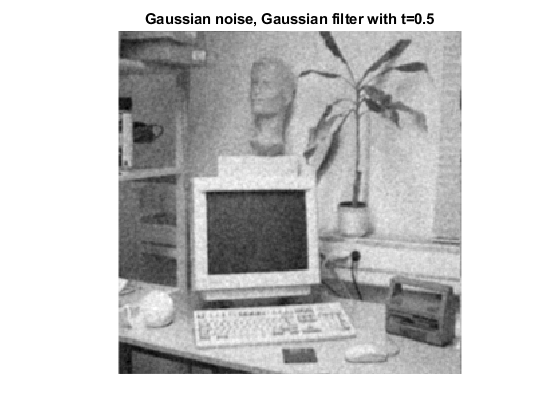


showgrey(gaussfft(add, 0.5));
title("Gaussian noise, Gaussian filter with t=0.5")

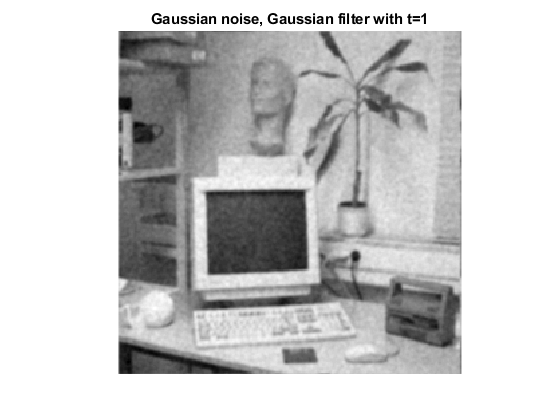

showgrey(gaussfft(add, 1));
title("Gaussian noise, Gaussian filter with t=1")

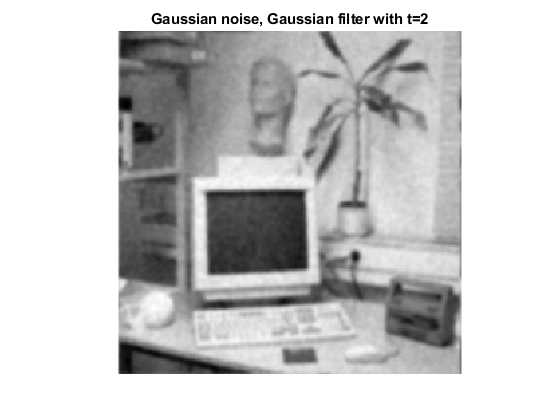

showgrey(gaussfft(add, 2));
title("Gaussian noise, Gaussian filter with t=2")

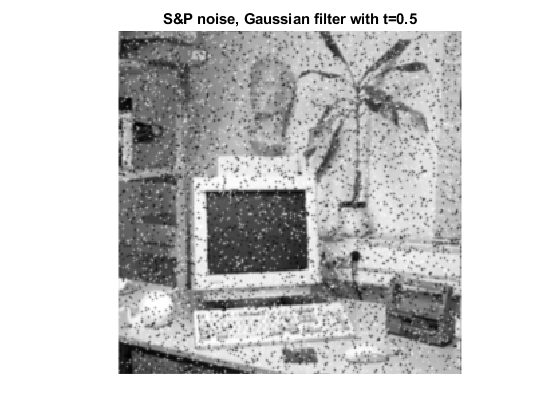


showgrey(gaussfft(sap, 0.5));
title("S&P noise, Gaussian filter with t=0.5")

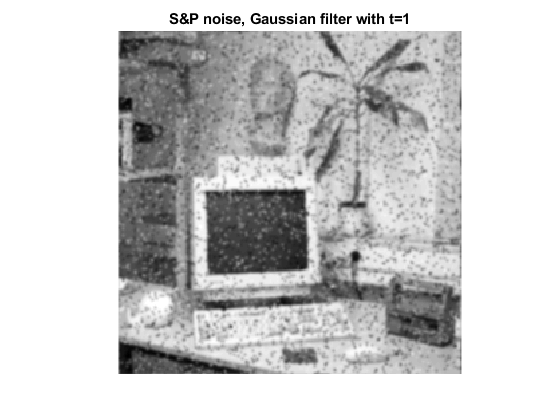

showgrey(gaussfft(sap, 1));
title("S&P noise, Gaussian filter with t=1")

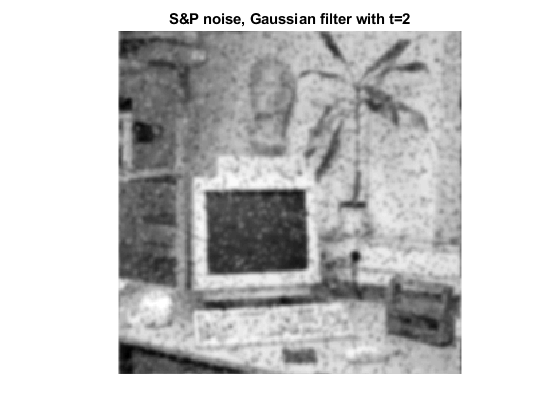

showgrey(gaussfft(sap, 2));
title("S&P noise, Gaussian filter with t=2")

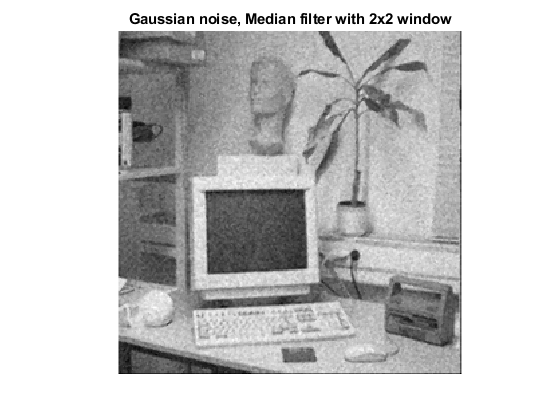


showgrey(medfilt(add, 2));
title("Gaussian noise, Median filter with 2x2 window")

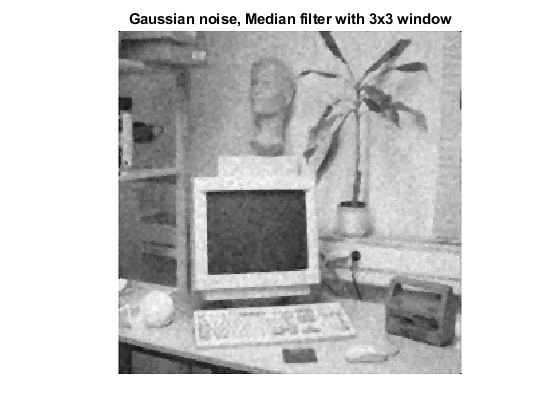

showgrey(medfilt(add, 3));
title("Gaussian noise, Median filter with 3x3 window")

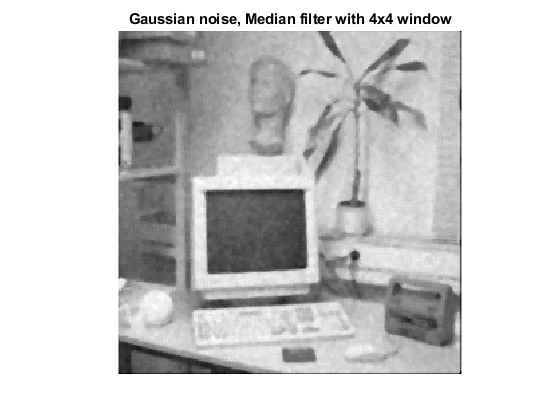

showgrey(medfilt(add, 4));
title("Gaussian noise, Median filter with 4x4 window")

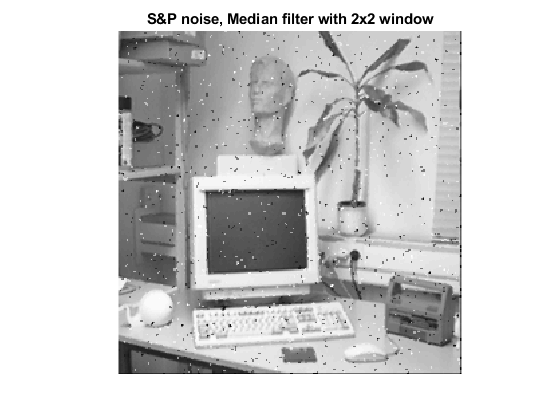


showgrey(medfilt(sap, 2));
title("S&P noise, Median filter with 2x2 window")

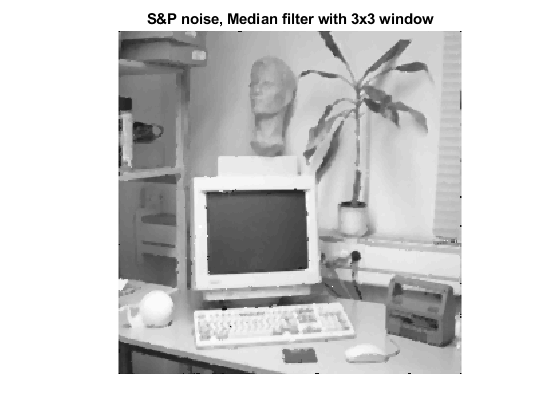

showgrey(medfilt(sap, 3));
title("S&P noise, Median filter with 3x3 window")

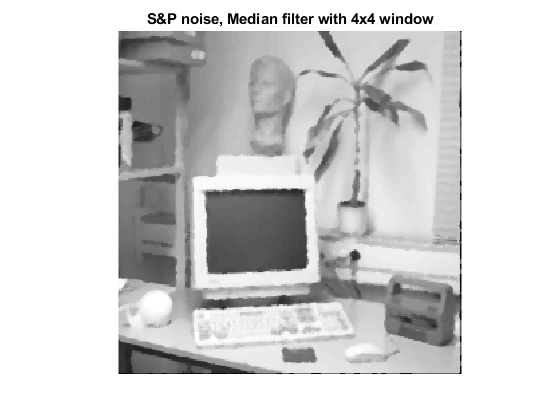

showgrey(medfilt(sap, 4));
title("S&P noise, Median filter with 4x4 window")

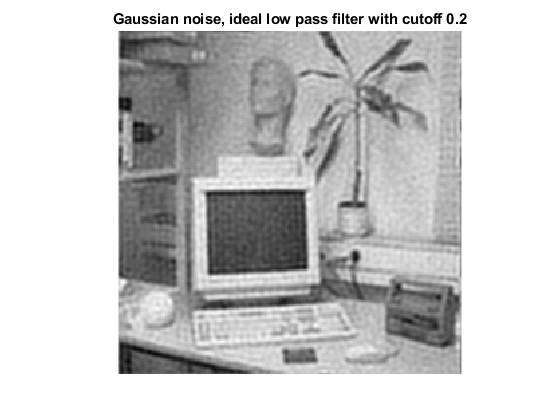



showgrey(ideal(add, 0.2));
title("Gaussian noise, ideal low pass filter with cutoff 0.2")

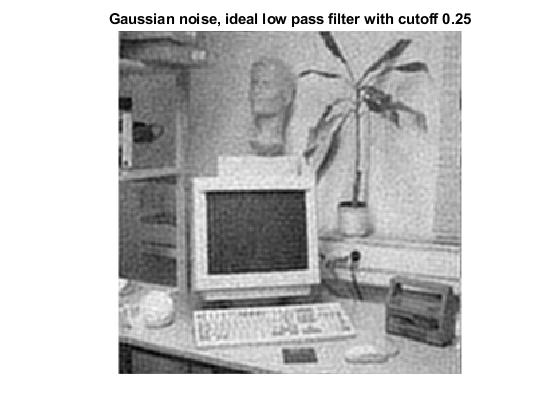

showgrey(ideal(add, 0.25));
title("Gaussian noise, ideal low pass filter with cutoff 0.25")

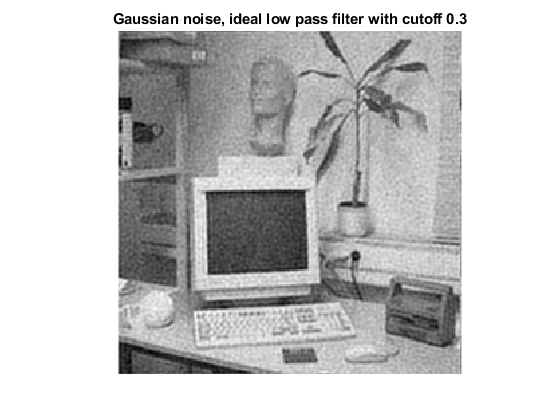

showgrey(ideal(add, 0.3));
title("Gaussian noise, ideal low pass filter with cutoff 0.3")

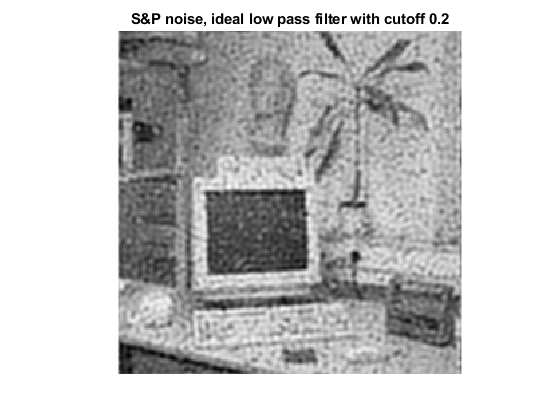


showgrey(ideal(sap, 0.2));
title("S&P noise, ideal low pass filter with cutoff 0.2")

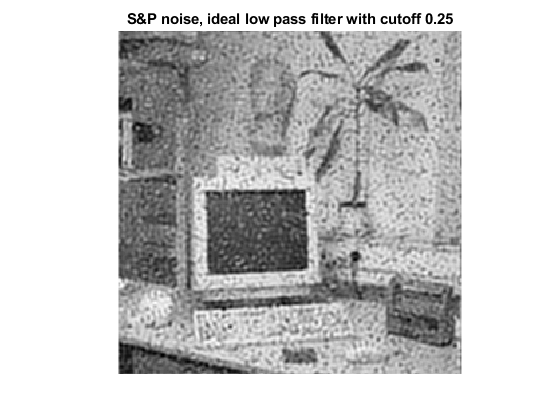

showgrey(ideal(sap, 0.25));
title("S&P noise, ideal low pass filter with cutoff 0.25")

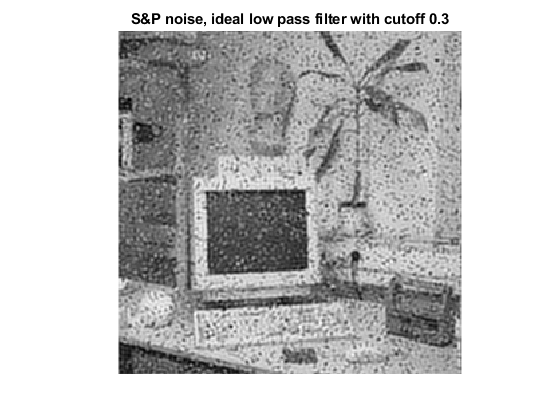

showgrey(ideal(sap, 0.3));
title("S&P noise, ideal low pass filter with cutoff 0.3")


% subplot(2,3,1);
% showgrey(gaussfft(add, 0.1));
% subplot(2,3,2);
% showgrey(gaussfft(add, 0.3));
% subplot(2,3,3);
% showgrey(gaussfft(add, 0.5));
% 
% subplot(2,3,4);
% showgrey(gaussfft(sap, 0.1));
% subplot(2,3,5);
% showgrey(gaussfft(sap, 0.3));
% subplot(2,3,6);
% showgrey(gaussfft(sap, 0.5));